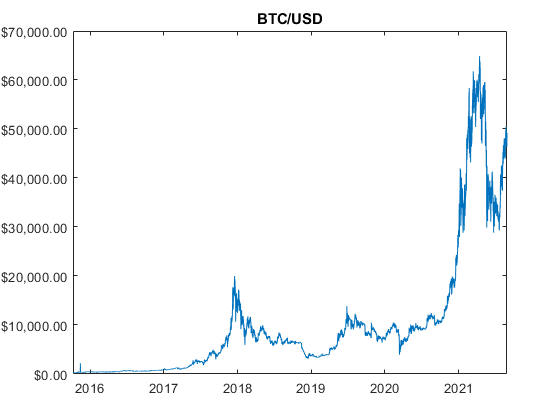

%% Figure 1

figure (1)
plot(Yfull.Date, Yfull.Close)
ytickformat('usd')
title(['BTC/USD'])

%Need to load full Data

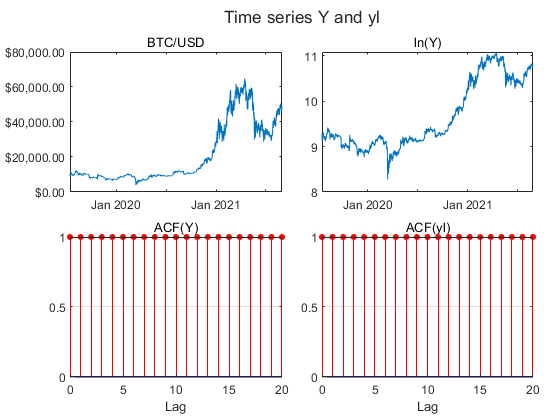

%% Figure 2

earlyData =  tiledlayout(2,2,"TileSpacing","compact","Padding","compact");

title(earlyData,'Time series Y and yl')

nexttile
plot(Y.Date, Y.Close)
ytickformat('usd')
xlim([datetime(2019,7,16,10,8,34)...
       datetime(2021,8,28,10,8,34)])
subtitle('BTC/USD')

nexttile
plot(Y.Date,yl)
xlim([datetime(2019,7,16,10,8,34)...
       datetime(2021,8,28,10,8,34)])
subtitle('ln(Y)')

nexttile
autocorr(Y.Close)
subtitle("ACF(Y)")
title('')
ylabel('')

nexttile
autocorr(yl)
subtitle("ACF(yl)")
title('')
ylabel('')

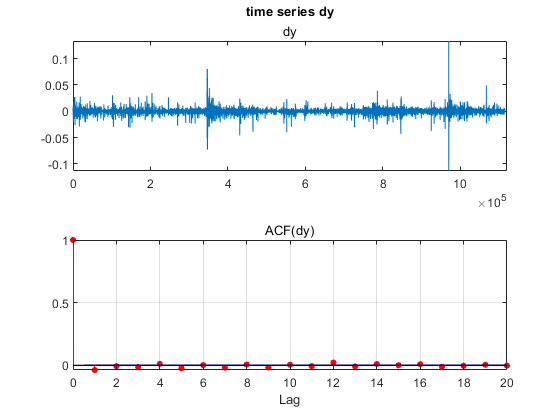

%% Figure 3

figure (3)
subplot(2,1,1)
plot(dy)
title('time series dy')
subtitle("dy")
xlim([0 1120123])
subplot(2,1,2)
autocorr(dy)
ylabel('')
title('')
subtitle("ACF(dy)")

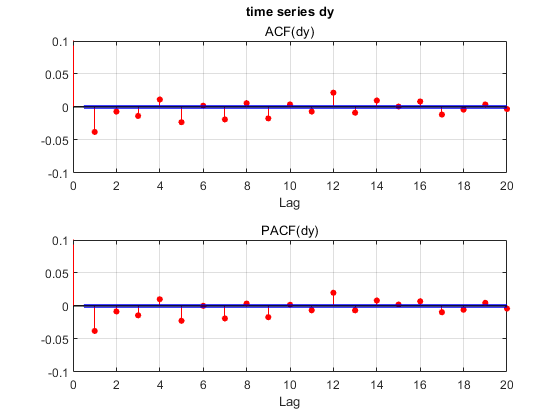

%% Figure 4

figure(4)
subplot(2,1,1) 
autocorr(dy)
title('time series dy')
subtitle("ACF(dy)")
ylabel('')
ylim([-0.1 0.1])
subplot(2,1,2)
parcorr(dy)
title('')
subtitle("PACF(dy)")
ylabel('')
ylim([-0.1 0.1])

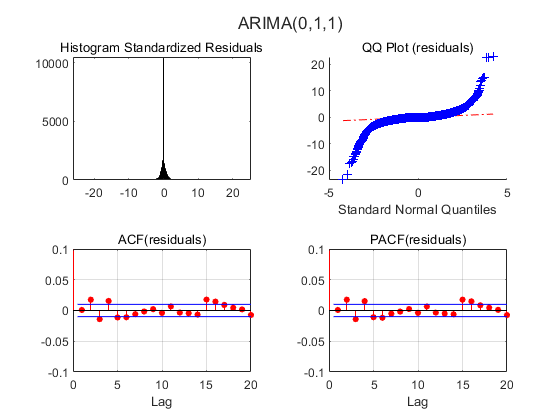

%% Figure 7 / 8 / 9


v= tiledlayout(2,2);
% title(v,'ARIMA(0,1,17)')
% title(v,'ARIMA(0,1,6)')
title(v,'ARIMA(0,1,1)')
nexttile
histogram(stres)
subtitle('Histogram Standardized Residuals')
title('')

nexttile
qqplot(stres)
ylabel('')
title('')
subtitle('QQ Plot (residuals)')

nexttile
autocorr(residuals)
subtitle("ACF(residuals)")
ylim([-0.1 0.1])
ylabel('')
title('')

nexttile
parcorr(residuals)
subtitle("PACF(residuals)")
ylim([-0.1 0.1])
ylabel('')
title('')

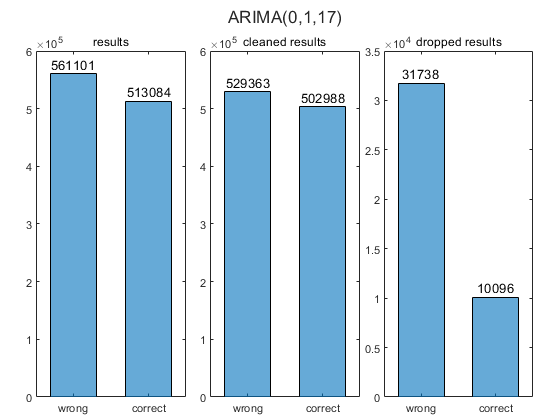

%% Figure 11 / 12 /13

tiledResults =  tiledlayout(1,3,"TileSpacing","compact","Padding","compact");

title(tiledResults,'ARIMA(0,1,17)')
% title(tiledResults,'ARIMA(0,1,6)')
% title(tiledResults,'ARIMA(0,1,1)')

nexttile
h= histogram(categorical(results,[0 1], {'wrong','correct'}),'BarWidth',0.618);
hy = h.Values;
text(1:2, hy+17000, string(hy),"HorizontalAlignment","center");
subtitle('results',"Clipping","off")

nexttile
h= histogram(categorical(cleanedresults,[0 1], {'wrong','correct'}),'BarWidth',0.618);
hy = h.Values;
text(1:2, hy+17000, string(hy),"HorizontalAlignment","center");
subtitle('cleaned results');

nexttile
h= histogram(categorical(results(~mask(Ts+1:jj+Ts)),[0 1], {'wrong','correct'}),'BarWidth',0.618);
hy = h.Values;
text(1:2, hy+1000, string(hy),"HorizontalAlignment","center");
subtitle('dropped results',"Clipping","on")